# MATLAB: Arrays and Operations

MATLAB deals with arrays (matrices) of any type efficiently. This is its competitive advantage. To take advantage of this, you need to understand how to deal with the arrays in MATLAB.

## Data Types in MATLAB

There are many types of data in MATLAB. Each data type can be manipulated in unique ways using a variety of functions

### Numeric types

- `Double` - double precision arrays

- `Single` - single precision arrays

- `int8` / `uint8` - 8 bit integers

- `int16` / `uint16` - 16 bit integers

- `int32` / `uint32` - 32 bit integers

- `int64` / `uint64` - 64 bit integers

### Text types

- `char` - array of elements that must contain the same number of characters 

- `strings` - array of elements that contain any number of characters

### Other types

- `Date and Time`

- `Tables`

- `Structures`

- `Cell arrays`

- `Function Handles`

## Things to keep in mind

In MATLAB, everything is an array

- numeric arrays

- character arrays

- string arrays

- cell arrays

With numeric arrays, standard operators (`+|-|*|/`) take on different meanings when preceded by a `'.'. T`he `'.'` indicates 'element by element' operations

## Numeric Arrays: Indexing

Numeric Arrays refer to vectors and any higher dimensional matrices. There are two ways of referencing an array

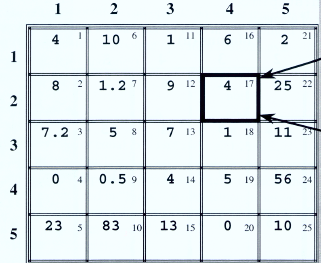

- 2+ indices: specify row and column, ...

a=magic(4)
a(2,3)

- 1 index: runs down each column

a(11)

## Numeric Arrays: Creating

Array elements must be enclosed by` […]`. Columns are separated by a `<space>` or` ,` and rows are separated by a `;`

A = [1,2 3;4 5 ,6; 7 8 9]

MATLAB has a very special operator `':'. This s`aves typing when creating a numeric array

A = 1:9
B = 1:2:9
A = reshape(A,3,3)
A'

## Numeric Arrays: Combining

MATLAB makes it easy to combine (or concatenate) arrays, just make sure the dimensions work out.

B = [1,3,7]
C = [A; B]
C = [A B']

## Numeric Arrays: Operations

MATLAB can operate element by element or matrix-wise depending on the syntax

What does … give?

A*A
A.*A
A*B'
A.*B'

## Character and String Arrays

These arrays operate in the same manner as numeric arrays, just with different data types, characters. You can index into, reshape, and concatenate string arrays using standard array operations, and you can append text to strings using the + operator

Type `doc` `string` for more info 

Character arrays are arrays of single elements

char1 = 'kelley'
char1'
char1(3)
char2 = ['k','e','l','l','e','y']

Can concatenate them?

char3 = 'tom'
%char13 = char1+char3

Oooo, maybe not!

char12 = char1+char2
char(char12)

How are we suppose to deal with strings? Well, with a string array - 

str1 = "kelley"
str2 = ["k", "e", "l","l","e","y"]
str12 = str1+str2
str3 = [str1; "string of a totally different length"]

## Cell Arrays

A cell array is a data type with indexed data containers called cells. Each *cell* can contain any type of data,

C = {1,2,3;'one', 'two',"three"}

When using cell arrays remember:

- Use {} to reference the values within the cell array

- Use () to get a sub-”cell” array

- Cell arrays are flexible, but sometimes are difficult to work with

element1 = C{2,3}
cell1 = C(:,3)

## Useful Functions

A = [1,3,5;-1,8,9;-4,5,-2;1,1,5]
B = 2:0.5:9

Number of elements

numel(A)
numel(B)

Size of array

size(A)
size(B)

Length of Array

length(A)
length(B)
B(B~=4|B>7)